clear; clc; close all;


## Get VOI Timeseries

spm_mat_file = '/Users/abhijitc/Documents/Abhijit/LenaLab_DCM/Github/SPM5_SpectralDCM_RestData/glm/SPM.mat';
mask_file = '/Users/abhijitc/Documents/Abhijit/LenaLab_DCM/Github/SPM5_SpectralDCM_RestData/glm/mask.nii,1';
radius = 6;

get_VOI(spm_mat_file, mask_file, 'PCC', [0 -52 26], radius);



------------------------------------------------------------------------
11-Jul-2025 18:38:25 - Running job #2
------------------------------------------------------------------------
11-Jul-2025 18:38:25 - Running 'Volume of Interest'
   VOI saved as /Users/abhijitc/Documents/Abhijit/LenaLab_DCM/spDCM/glm/VOI_PCC_1.mat
11-Jul-2025 18:38:27 - Done    'Volume of Interest'
11-Jul-2025 18:38:27 - Done



get_VOI(spm_mat_file, mask_file, 'mPFC', [3 54 -2], radius);



------------------------------------------------------------------------
11-Jul-2025 18:38:29 - Running job #2
------------------------------------------------------------------------
11-Jul-2025 18:38:29 - Running 'Volume of Interest'
   VOI saved as /Users/abhijitc/Documents/Abhijit/LenaLab_DCM/spDCM/glm/VOI_mPFC_1.mat
11-Jul-2025 18:38:30 - Done    'Volume of Interest'
11-Jul-2025 18:38:30 - Done



get_VOI(spm_mat_file, mask_file, 'lIPC', [-50 -63 32], radius);



------------------------------------------------------------------------
11-Jul-2025 18:38:31 - Running job #2
------------------------------------------------------------------------
11-Jul-2025 18:38:31 - Running 'Volume of Interest'
   VOI saved as /Users/abhijitc/Documents/Abhijit/LenaLab_DCM/spDCM/glm/VOI_lIPC_1.mat
11-Jul-2025 18:38:32 - Done    'Volume of Interest'
11-Jul-2025 18:38:32 - Done



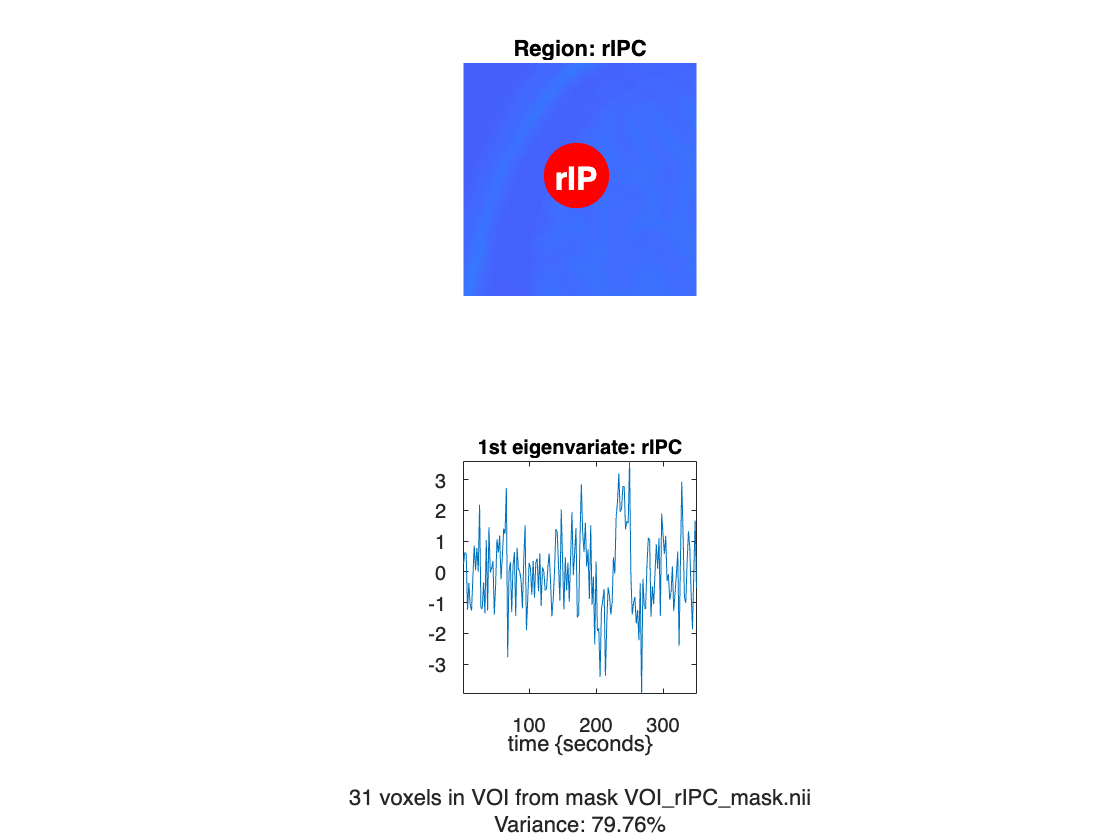



------------------------------------------------------------------------
11-Jul-2025 18:38:33 - Running job #2
------------------------------------------------------------------------
11-Jul-2025 18:38:33 - Running 'Volume of Interest'
   VOI saved as /Users/abhijitc/Documents/Abhijit/LenaLab_DCM/spDCM/glm/VOI_rIPC_1.mat


11-Jul-2025 18:38:34 - Done    'Volume of Interest'
11-Jul-2025 18:38:34 - Done



get_VOI(spm_mat_file, mask_file, 'rIPC', [48 -69 35], radius);

## Specifying and estimating the DCM

DCM.xY(1) = load('VOI_PCC_1.mat');   % Load VOI files
DCM.xY(2) = load('VOI_mPFC_1.mat');
DCM.xY(3) = load('VOI_lIPC_1.mat');
DCM.xY(4) = load('VOI_rIPC_1.mat');

DCM.n = length(DCM.xY);  % Number of VOIs

% DCM params

DCM.a = ones(DCM.n, DCM.n);  % Full connectivity (4x4 matrix of ones)
DCM.b = zeros(DCM.n, DCM.n, 0);  % No modulatory input 
DCM.c = zeros(DCM.n, 0);        % No driving input
DCM.d = zeros(DCM.n, DCM.n, 0); % No nonlinear effects

% 

## Functions

function [] = get_VOI(spm_mat_file, mask_file, VOI_name, centre, radius)

% Start batch
clear matlabbatch;
matlabbatch{1}.spm.util.voi.spmmat = {spm_mat_file};
matlabbatch{1}.spm.util.voi.adjust = NaN;
matlabbatch{1}.spm.util.voi.session = 1;
matlabbatch{1}.spm.util.voi.name = VOI_name;
matlabbatch{1}.spm.util.voi.roi{1}.sphere.centre = centre;
matlabbatch{1}.spm.util.voi.roi{1}.sphere.radius = radius;
matlabbatch{1}.spm.util.voi.roi{1}.sphere.move.fixed = 1;
matlabbatch{1}.spm.util.voi.roi{2}.mask.image = {mask_file};
matlabbatch{1}.spm.util.voi.roi{2}.mask.threshold = 0.5;
matlabbatch{1}.spm.util.voi.expression = 'i1&i2';

% Run the batch
spm_jobman('run',matlabbatch);

end